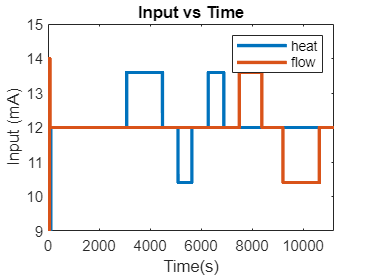

clear
clc
%%% Loading Data
data = load('B6A_OPENLOOP.txt');
n = 11078;  % number of rows of data
time = data(1:n,1);
temp = data(1:n,2);
heat = data(1:n,3);
flow = data(1:n,4);
dU = 1.6;
U=12;

plot(time,heat,LineWidth=2)
hold on
plot(time,flow,LineWidth=2)
hold off
legend('heat','flow')
ylim([9,15])
xlabel("Time(s)")
ylabel("Input (mA)")
title("Input vs Time")

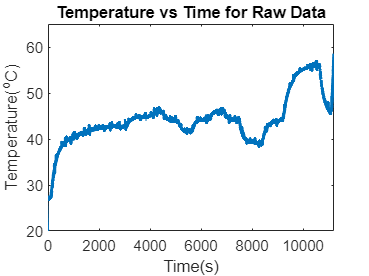


plot(time,temp,LineWidth=2)
xlabel("Time(s)")
ylim([20,65])
ylabel("Temperature(^oC)")
title("Temperature vs Time for Raw Data")

Our Initial Setting up values were errorneous, so slicing the initial part.

a = 4700;
time = data(a:n,1);
temp = data(a:n,2);
heat = data(a:n,3);
flow = data(a:n,4);

plot(time,temp,LineWidth=2)
hold on
xlabel("Time(s)")
%ylim([20,65])
ylabel("Temperature(^oC)")
title("Temperature vs Time")

Sharp Spikes in the data is due to the noise in the measurement. Removing the error 

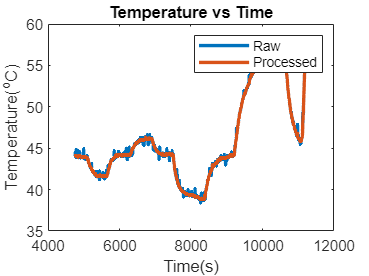

% requires signal processing toolbox
temp_filtered = medfilt1(temp,10);
temp_filtered(1) =  temp_filtered(2);
plot(time,temp_filtered,LineWidth=2)
hold off
legend('Raw','Processed')

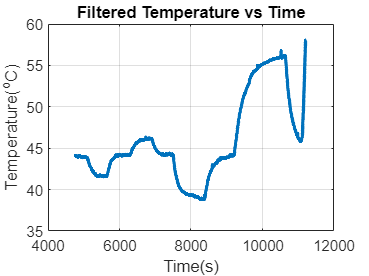


plot(time,temp_filtered,LineWidth=2)
title("Filtered Temperature vs Time")
grid on
xlabel("Time(s)")
ylabel("Temperature(^oC)")

A plot with input and output together

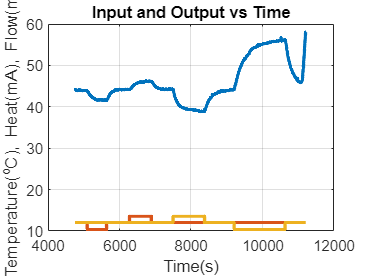

plot(time,temp_filtered,LineWidth=2)
hold on
title("Input and Output vs Time")
grid on
xlabel("Time(s)")
ylabel("Temperature(^oC), Heat(mA), Flow(mA)")
plot(time,heat,LineWidth=2)
plot(time,flow,LineWidth=2)
hold off

Determining the Steady State Values

SS_U1 = find(heat==U-dU,1);
temp_SS_U1 = mean(temp_filtered(SS_U1-50:SS_U1-1)) %steady-state temp

temp_SS_U1 = 43.9090

heat_SS_U1 = mean(heat(SS_U1-50:SS_U1-1)) %steady-state heat current

heat_SS_U1 = 12

For Changing Manipulated Variable (Heater)

SS_U_N_H = find(heat==U & time>5500,1);
temp_SS_U_N_H = mean(temp_filtered(SS_U_N_H-50:SS_U_N_H-1)) %steady-state temp

temp_SS_U_N_H = 41.6507

heat_SS_U_N_H = mean(heat(SS_U_N_H-50:SS_U_N_H-1)) %steady-state heat

heat_SS_U_N_H = 10.4000

**PLOTTING for negative input change (Manipulated)**

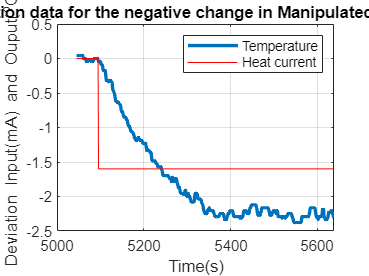

plot(time(SS_U1-50: SS_U_N_H-1),temp_filtered(SS_U1 - 50:SS_U_N_H-1)- temp_SS_U1,LineWidth=2)
hold on
plot(time(SS_U1-50: SS_U_N_H-1),heat(SS_U1-50:SS_U_N_H-1)- heat_SS_U1,"r")
hold off
title("Deviation data for the negative change in Manipulated Variable")
legend("Temperature","Heat current")
xlabel("Time(s)")
ylabel("Deviation Input(mA) and Ouput(^oC)")
grid on

Method : Calculating K and tau

% Graphical
K_N_H = (temp_SS_U_N_H-temp_SS_U1)/(heat_SS_U_N_H-heat_SS_U1)

K_N_H = 1.4114

yc = 0.633*(temp_SS_U_N_H-temp_SS_U1);

if(yc<=0)
 n_c = find(temp_filtered - temp_SS_U1 - yc <= 0,1);
else
 n_c = find(temp_filtered-temp_SS_U1 - yc >= 0,1);
end
t_c = time(n_c);
% t(find(heater-heater_s,1))
% t(idx_s)
tau_N_H= t_c-time(SS_U1)

tau_N_H = 122.4530


% Optimization Method
%del_N_H_heat = heat(SS_U1:SS_U_N_H)-heat_SS_U_N_H;
del_N_H_temp = temp_filtered(SS_U1:SS_U_N_H)-temp_SS_U1;
t_NH = time(SS_U1:SS_U_N_H)-time(SS_U1);

f = @(x)sum(((x(1).*(-dU).*(1-exp(-t_NH/x(2)))) - del_N_H_temp).^2);

x0=[K_N_H,tau_N_H];
[x,~] = fminunc(f,x0); 


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



K_N_H_opt = x(1)

K_N_H_opt = 1.4837

tau_N_H_opt = x(2)

tau_N_H_opt = 124.5298

SS_U2 = find(heat==U+dU,1);
temp_SS_U2 = mean(temp_filtered(SS_U2-50:SS_U2-1)) %steady-state temp

temp_SS_U2 = 44.1837

heat_SS_U2 = mean(heat(SS_U2-50:SS_U2-1)) %steady-state heat current

heat_SS_U2 = 12


SS_U_P_H = find(heat==U & time>6500,1);
temp_SS_U_P_H = mean(temp_filtered(SS_U_P_H-50:SS_U_P_H-1)) %steady-state temp

temp_SS_U_P_H = 46.1434

heat_SS_U_P_H = mean(heat(SS_U_P_H-50:SS_U_P_H-1)) %steady-state heat

heat_SS_U_P_H = 13.6000

**PLOTTING for positive input change (Manipulated)**

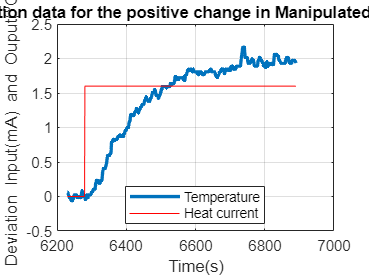

plot(time(SS_U2-50: SS_U_P_H-1),temp_filtered(SS_U2 - 50:SS_U_P_H-1)- temp_SS_U2,LineWidth=2)
hold on
plot(time(SS_U2-50: SS_U_P_H-1),heat(SS_U2-50:SS_U_P_H-1)- heat_SS_U2,"r")
hold off
title("Deviation data for the positive change in Manipulated Variable")
legend("Temperature","Heat current",Location="best" )
xlabel("Time(s)")
ylabel("Deviation Input(mA) and Ouput(^oC)")
grid on

Method : Calculating K and tau

% Graphical
K_P_H = (temp_SS_U_P_H-temp_SS_U2)/(heat_SS_U_P_H-heat_SS_U2)

K_P_H = 1.2248

yc = 0.633*(temp_SS_U_P_H-temp_SS_U2);

if(yc<=0)
 n_c = find(temp_filtered - temp_SS_U2 - yc <= 0,1);
else
 n_c = find(temp_filtered-temp_SS_U2 - yc >= 0,1);
end
t_c = time(n_c);
% t(find(heater-heater_s,1))
% t(idx_s)
tau_P_H= t_c-time(SS_U2)

tau_P_H = 148.7650


% Optimization Method
%del_P_H_heat = heat(SS_U2:SS_U_P_H)-heat_SS_U_P_H;
del_P_H_temp = temp_filtered(SS_U2:SS_U_P_H)-temp_SS_U2;
t_PH = time(SS_U2:SS_U_P_H)-time(SS_U2);

f = @(x)sum(((x(1).*(dU).*(1-exp(-t_PH/x(2)))) - del_P_H_temp).^2);

x0=[K_P_H,tau_P_H];
[x,~] = fminunc(f,x0); 


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



K_P_H_opt = x(1)

K_P_H_opt = 1.2970

tau_P_H_opt = x(2)

tau_P_H_opt = 172.4255

SS_U3 = find(flow==U+dU,1);
temp_SS_U3 = mean(temp_filtered(SS_U3-50:SS_U3-1)) %steady-state temp

temp_SS_U3 = 44.2291

heat_SS_U3 = mean(heat(SS_U3-50:SS_U3-1)) %steady-state heat current

heat_SS_U3 = 12

flow_SS_U3 = mean(flow(SS_U3-50:SS_U3-1)) %steady-state flow

flow_SS_U3 = 12

Now For Disturbance (Flow)

SS_U_P_F = find(flow==U & time>8000,1);
temp_SS_U_P_F = mean(temp_filtered(SS_U_P_F-50:SS_U_P_F-1)) %steady-state temp

temp_SS_U_P_F = 38.8510

flow_SS_U_P_F = mean(flow(SS_U_P_F-50:SS_U_P_F-1)) %steady-state flow

flow_SS_U_P_F = 13.6000

**PLOTTING for positive input change (Disturbance)**

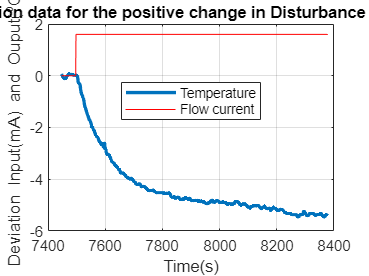

plot(time(SS_U3-50: SS_U_P_F-1),temp_filtered(SS_U3 - 50:SS_U_P_F-1)- temp_SS_U3,LineWidth=2)
hold on
plot(time(SS_U3-50: SS_U_P_F-1),flow(SS_U3-50:SS_U_P_F-1)- flow_SS_U3,"r")
hold off
title("Deviation data for the positive change in Disturbance Variable")
legend("Temperature","Flow current",Location="best" )
xlabel("Time(s)")
ylabel("Deviation Input(mA) and Ouput(^oC)")
grid on

Method : Calculating K and tau

% Graphical
K_P_F = (temp_SS_U_P_F-temp_SS_U3)/(flow_SS_U_P_F-flow_SS_U3)

K_P_F = -3.3613

yc = 0.633*(temp_SS_U_P_F-temp_SS_U3);

if(yc<=0)
 n_c = find(temp_filtered - temp_SS_U3 - yc <= 0,1);
else
 n_c = find(temp_filtered-temp_SS_U3 - yc >= 0,1);
end
t_c = time(n_c);
% t(find(heater-heater_s,1))
% t(idx_s)
tau_P_F= t_c-time(SS_U3)

tau_P_F = 134.5620


% Optimization Method
%del_P_F_heat = heat(SS_U3:SS_U_P_F)-heat_SS_U_P_F;
del_P_F_temp = temp_filtered(SS_U3:SS_U_P_F)-temp_SS_U3;
t_PF = time(SS_U3:SS_U_P_F)-time(SS_U3);

f = @(x)sum(((x(1).*(dU).*(1-exp(-t_PF/x(2)))) - del_P_F_temp).^2);

x0=[K_P_F,tau_P_F];
[x,~] = fminunc(f,x0); 


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



K_P_F_opt = x(1)

K_P_F_opt = -3.2205

tau_P_F_opt = x(2)

tau_P_F_opt = 130.4005

SS_U4 = find(flow==U-dU,1);
temp_SS_U4 = mean(temp_filtered(SS_U4-50:SS_U4-1)) %steady-state temp

temp_SS_U4 = 44.1567

flow_SS_U4 = mean(flow(SS_U4-50:SS_U4-1)) %steady-state flow

flow_SS_U4 = 12


SS_U_N_F = find(flow==U & time>9500,1);
temp_SS_U_N_F = mean(temp_filtered(SS_U_N_F-50:SS_U_N_F-1)) %steady-state temp

temp_SS_U_N_F = 56.1430

flow_SS_U_N_F = mean(flow(SS_U_N_F-50:SS_U_N_F-1)) %steady-state flow

flow_SS_U_N_F = 10.4000

PLOT for negative deviation in Disturbance

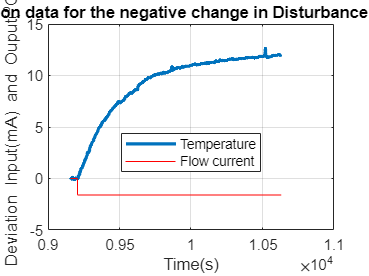

plot(time(SS_U4-50: SS_U_N_F-1),temp_filtered(SS_U4 - 50:SS_U_N_F-1)- temp_SS_U4,LineWidth=2)
hold on
plot(time(SS_U4-50: SS_U_N_F-1),flow(SS_U4-50:SS_U_N_F-1)- flow_SS_U4,"r")
hold off
title("Deviation data for the negative change in Disturbance Variable")
legend("Temperature","Flow current",Location="best" )
xlabel("Time(s)")
ylabel("Deviation Input(mA) and Ouput(^oC)")
grid 

Method : Calculating K and tau

% Graphical
K_N_F = (temp_SS_U_N_F-temp_SS_U4)/(flow_SS_U_N_F-flow_SS_U4)

K_N_F = -7.4914

yc = 0.633*(temp_SS_U_N_F-temp_SS_U4);

if(yc<=0)
 n_c = find(temp_filtered - temp_SS_U4 - yc <= 0,1);
else
 n_c = find(temp_filtered-temp_SS_U4 - yc >= 0,1);
end
t_c = time(n_c);
% t(find(heater-heater_s,1))
% t(idx_s)
tau_N_F= t_c-time(SS_U4)

tau_N_F = 321.7030


% Optimization Method
%del_N_F_heat = heat(SS_U4:SS_U_N_F)-heat_SS_U_N_F;
del_N_F_temp = temp_filtered(SS_U4:SS_U_N_F)-temp_SS_U4;
t_NF = time(SS_U4:SS_U_N_F)-time(SS_U4);

f = @(x)sum(((x(1).*(-dU).*(1-exp(-t_NF/x(2)))) - del_N_F_temp).^2);

x0=[K_N_F,tau_N_F];
[x,~] = fminunc(f,x0); 


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



K_N_F_opt = x(1)

K_N_F_opt = -7.4475

tau_N_F_opt = x(2)

tau_N_F_opt = 301.4070

**The Final Steady State after resetting the Disturbance was not obtained due to shutting off of the air supply to valve due to external factors.**

But an assumption based on prior steady state values is taken as.

SS_U5 = mean([temp_SS_U1,temp_SS_U4,temp_SS_U2,temp_SS_U3])

SS_U5 = 44.1196

# Controller Response

K_p = 0.5*(K_P_H_opt+K_N_H_opt)

K_p = 1.3903

tau_p = 0.5*(tau_P_H_opt+tau_N_H_opt)

tau_p = 148.4777


K_d = 0.5*(K_P_F_opt+K_N_F_opt)

K_d = -5.3340

tau_d = 0.5*(tau_P_F_opt+tau_N_F_opt)

tau_d = 215.9037


% TODO
alpha1 = 1.6

alpha1 = 1.6000

alpha2 = 2.65

alpha2 = 2.6500

K_c1 = (alpha1-1)/K_p

K_c1 = 0.4315

K_c2 = (alpha2-1)/K_p

K_c2 = 1.1868

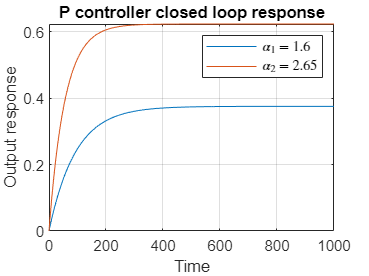



syms t s
H1 = K_c1*K_p*(1/s)/(tau_p*s+ 1+ K_c1*K_p);
H2 = K_c2*K_p*(1/s)/(tau_p*s+ 1+ K_c2*K_p);
h1=matlabFunction(ilaplace(H1));
h2=matlabFunction(ilaplace(H2));
t = 0:1.003:1000;

plot(t, h1(t))
hold on
plot(t,h2(t))
hold off
grid
title('P controller closed loop response')
leg1 = legend('$\alpha_1 = 1.6$', '$\alpha_2 = 2.65$');
set(leg1,'Interpreter','latex');
xlabel('Time')
ylabel('Output response')

#### PI Controller

alpha_PI = 2.15;

%TODO
zeta_1 = 0.8; %(underdamped)
zeta_2 = 1.21; %(overdamped)

K_PI_c1 = (2*alpha_PI*zeta_1 - 1)/K_p

K_PI_c1 = 1.7550

K_PI_c2 = (2*alpha_PI*zeta_2 - 1)/K_p

K_PI_c2 = 3.0230


tau_i_1= (2*alpha_PI*zeta_1 - 1)*tau_p/(alpha_PI^2)

tau_i_1 = 78.3744

tau_i_2= (2*alpha_PI*zeta_2 - 1)*tau_p/(alpha_PI^2)

tau_i_2 = 135.0030

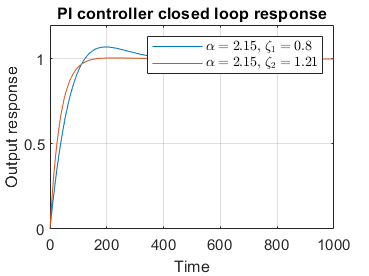


syms t3 s
t3 = 0:1.031:1000;
H_PI_1 = (tau_i_1*s + 1)*(1/s)/ ((tau_p*tau_i_1*s^2/(K_PI_c1*K_p))+(tau_i_1*s/(K_PI_c1*K_p/(1+K_PI_c1*K_p)))+1);
H_PI_2 = (tau_i_2*s + 1)*(1/s)/ ((tau_p*tau_i_2*s^2/(K_PI_c2*K_p))+(tau_i_2*s/(K_PI_c2*K_p/(1+K_PI_c2*K_p)))+1); 
h1_PI=matlabFunction(ilaplace(H_PI_1));
h2_PI=matlabFunction(ilaplace(H_PI_2));
plot(t3,h1_PI(t3))
hold on
plot(t3,h2_PI(t3))
hold off
grid
title('PI controller closed loop response')
legend('$\alpha = 2.15$, $\zeta_1 = 0.8$', '$\alpha = 2.15$, $\zeta_2=1.21$','Interpreter','latex');
xlabel('Time')
ylabel('Output response')

OPEN LOOP RESPONSES

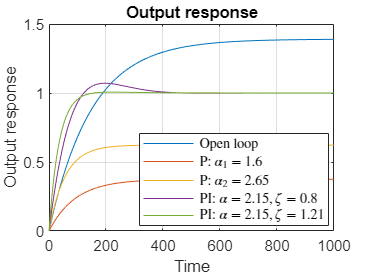

syms t4 s
t4 = 0:1.031:1000;
hh_open = K_p*(1/s)/(tau_p*s + 1); %open loop response
h_open=matlabFunction(ilaplace(hh_open));
figure(3)
plot(t4,h_open(t4),t4,h1(t4),t4,h2(t4),t4,h1_PI(t4),t4,h2_PI(t4))
grid()
title('Output response')
legend('Open loop', 'P: $\alpha_1 = 1.6$', 'P: $\alpha_2 = 2.65$','PI: $\alpha = 2.15, \zeta = 0.8$','PI: $\alpha = 2.15, \zeta = 1.21$','interpreter' ,'latex',Location='best');
xlabel('Time')
ylabel('Output response') 

COMPARISON

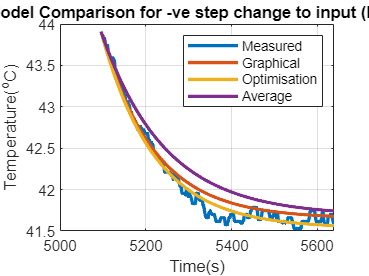

% For NEGATIVE MANIPULATED
graph =temp_SS_U1+ K_N_H.*(-dU).*(1-exp(-t_NH/tau_N_H));
opt = temp_SS_U1+K_N_H_opt.*(-dU).*(1-exp(-t_NH/tau_N_H_opt));
avg = temp_SS_U1+K_p.*(-dU).*(1-exp(-t_NH/tau_p));
t_plot = time(SS_U1:SS_U_N_H);
plot(t_plot,temp_filtered(SS_U1 :SS_U_N_H),LineWidth=2)
hold on
plot(t_plot,graph,LineWidth=2)
plot(t_plot,opt,LineWidth=2)
plot(t_plot,avg,LineWidth=2)
hold off
title("Model Comparison for -ve step change to input (Heat)")
ylabel("Temperature(^oC)")
xlabel("Time(s)")
legend("Measured","Graphical","Optimisation","Average")
grid

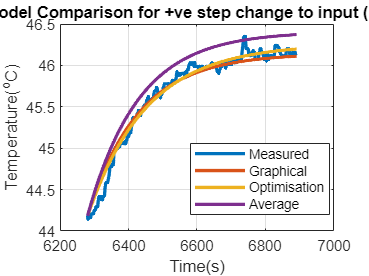


% For Positive MANIPULATED
graph =temp_SS_U2+ K_P_H.*(dU).*(1-exp(-t_PH/tau_P_H));
opt = temp_SS_U2+K_P_H_opt.*(dU).*(1-exp(-t_PH/tau_P_H_opt));
avg = temp_SS_U2+K_p.*(dU).*(1-exp(-t_PH/tau_p));
t_plot = time(SS_U2:SS_U_P_H);
plot(t_plot,temp_filtered(SS_U2 :SS_U_P_H),LineWidth=2)
hold on
plot(t_plot,graph,LineWidth=2)
plot(t_plot,opt,LineWidth=2)
plot(t_plot,avg,LineWidth=2)
hold off
title("Model Comparison for +ve step change to input (Heat)")
ylabel("Temperature(^oC)")
xlabel("Time(s)")
legend("Measured","Graphical","Optimisation","Average",Location="best")
grid

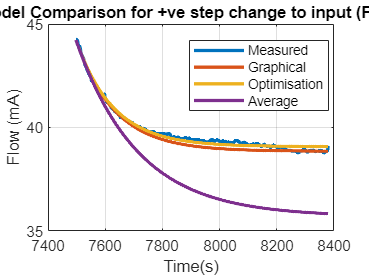



% For Positive Disturbance
graph =temp_SS_U3+ K_P_F.*(dU).*(1-exp(-t_PF/tau_P_F));
opt = temp_SS_U3+K_P_F_opt.*(dU).*(1-exp(-t_PF/tau_P_F_opt));
avg = temp_SS_U3+K_d.*(dU).*(1-exp(-t_PF/tau_d));
t_plot = time(SS_U3:SS_U_P_F);
plot(t_plot,temp_filtered(SS_U3 :SS_U_P_F),LineWidth=2)
hold on
plot(t_plot,graph,LineWidth=2)
plot(t_plot,opt,LineWidth=2)
plot(t_plot,avg,LineWidth=2)
hold off
title("Model Comparison for +ve step change to input (Flow)")
ylabel("Flow (mA)")
xlabel("Time(s)")
legend("Measured","Graphical","Optimisation","Average",Location="best")
grid

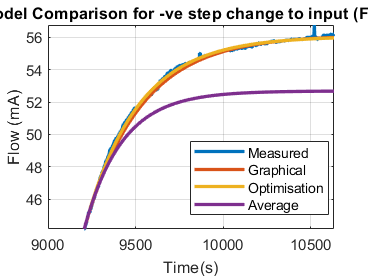


% For Negative Disturbance
graph =temp_SS_U4+ K_N_F.*(-dU).*(1-exp(-t_NF/tau_N_F));
opt = temp_SS_U4+K_N_F_opt.*(-dU).*(1-exp(-t_NF/tau_N_F_opt));
avg = temp_SS_U4+K_d.*(-dU).*(1-exp(-t_NF/tau_d));
t_plot = time(SS_U4:SS_U_N_F);
plot(t_plot,temp_filtered(SS_U4 :SS_U_N_F),LineWidth=2)
hold on
plot(t_plot,graph,LineWidth=2)
plot(t_plot,opt,LineWidth=2)
plot(t_plot,avg,LineWidth=2)
hold off
title("Model Comparison for -ve step change to input (Flow)")
ylabel("Flow (mA)")
xlabel("Time(s)")
legend("Measured","Graphical","Optimisation","Average",Location="best")
grid